# Repeated Operations – For Loops

Often, we want to repeat operations multiple times. *For loops* allow us to repeat operations a specified number of times. The general structure of a for loop is

Where

- `for` and `end` indicate the beginning and the end of the for loop

- `index` is a variable that changes on each loop

- `values` defines how `index `changes on each loop

- `statements` is the set of commands executed each time the loop runs

#### Example: Counting by 2

An example might help us better understand how these variables work. Let's write a simple for loop that counts from 0 to n by 2.

n = 20; % define the maximum value to count to
% define the loop index (k) as ranging from 0 to n, by 2
for  k = 0:2:n
    disp(k) % display the loop counter 
end

     0
     2
     4
     6
     8
    10
    12
    14
    16
    18
    20


#### Example: Counting backwards by 3

Rework the previous example to count backwards from n to 0, by 3.

n = 21; % define n
for k = n:-3:0
    disp(k) % display the loop counter 
end

    21
    18
    15
    12
     9
     6
     3
     0


## Anatomy of a For Loop

There are two primary pieces of a for loop: the loop index variable and the code that executes on each loop.

### The Loop Index Variable

In general, we can think of the loop index variable as being defined as

Let's think about the value of `k` on each loop:

- First loop, `k = f`

- Second loop,` k = f + s`

- Third loop,` k = f + s + s`

- ...

- nth loop, `k = f + s*(n-1)`

- ...

- Last loop, `k = f + s*floor((t-f)/s)`

The `floor() `function rounds the input toward negative infinity. For example, `floor(11.3) = 11`. Let's look at some of the consequences of the formula for the value of `k` on the last loop.

Reconsider the counting by 2 example above, but set the maximum value of the loop index variable to an odd number.

n = 21; % define the maximum value to count to
% define the loop index (k) as ranging from 0 to n, by 2
for k = 0:2:n
     disp(k) % display the loop counter 
end

     0
     2
     4
     6
     8
    10
    12
    14
    16
    18
    20


n = 19; % define the maximum value to count to
A = [];
i=1;
% define the loop index (k) as ranging from 0 to n, by 2
for k = 0:2:n
    A(i)=k;
    i=i+1; 
end
disp(A)

     0     2     4     6     8    10    12    14    16    18


We see that the code only counts to the nearest even number smaller than n.

### The Executable Code Inside the Loop

This is the *task* we want to run repeatedly. There are 2 primary ways we can think about this executable code:

- Operations that directly depend on the loop index variable, and

- Operations that don't directly depend on the loop index variable (i.e., the loop index variable really just acts as a counter/placeholder for the primary operations you're performing).

In either case, we **must not redefine the loop index variable inside the loop!** If our loop index variable is `k`, statements like

should **NEVER** be inside our loop structure.

#### Operations Directly Depending on Loop Index Variable

These type of operations use the loop index variable directly when defining new variables inside the looping structure. For example, the alternating harmonic series is defined as


$$\sum_{n=1}^{\infty \;} \frac{{\left(-1\right)}^{n+1} }{n}=1-\frac{1}{2}+\frac{1}{3}-\frac{1}{4}+\;\ldotp \ldotp \ldotp$$


The so-called partial sum of the alternating harmonic series is 


$$\sum_{n=1}^{N\;} \frac{{\left(-1\right)}^{n+1} }{n}=1-\frac{1}{2}+\frac{1}{3}-\frac{1}{4}+\;\ldotp \ldotp \ldotp +\frac{{\left(-1\right)}^{N+1} }{N}$$


We can write a for loop to calculate the partial sum of the alternating harmonic series up to N terms.

N = 10; % define the number of terms in the partial sum
S = 0; % initialize the value of the partial sum
% define the loop parameters
for k = 1:1:N % (or k = 1:N, defult)
    % the partial sum of the alternating harmonic series is defined as the
    % previous value of the sum plus the new term (i.e., the Nth term)
    S = S + (-1)^(k+1)/k;
end
format short
disp(S)

    0.6456


#### Operations Indirectly Depending on Loop Index Variable

For these types of operations, the loop index variable acts more like a placeholder. For example, consider wanting to display the elements of an $m\times n$ matrix one-by-one, counting along the rows. This task doesn't require us to define anything explicitly in terms of our loop index variable (e.g., by multiplying or dividing by the loop index variable itself), but we do have to reference the loop index variable to perform the task.

Let's first visualize what we are trying to do. Consider the matrix $\mathit{\mathbf{A}}$,


$$\textbf{A} =
\left [\matrix{
a_{11} & a_{12} & \dots & a_{1n} \cr
a_{21} & a_{22} & \dots & a_{2n} \cr
\vdots & \vdots & \ddots & \vdots \cr
a_{m1} & a_{m2} & \dots & a_{mn}
} \right ]$$


We want to display the elements of $\mathit{\mathbf{A}}$in the following order:


$$a_{11} ,\;a_{12} ,\ldots,\;a_{1n} ,\;a_{21} ,{\;a}_{22} ,\ldots,\;a_{2n} ,\ldots,\;a_{m1} ,\;a_{m2} ,\ldots,\;a_{\textrm{mn}}$$


Our algorithm is:

- Stop at row (starting form first)

- display elements for each column in that row, in ascending column order

- once we've reached end of row, move to next row

-  repeat 1 through 3 for all rows of matrix

A = [1 2 3;
    4 5 6;
    7 8 9];
% outter loop to count through rows
for m = 1:size(A,1)
    % inner loop to count through columns
    for n = 1:size(A,2)
        disp(A(m,n)) % display element (m,n)
    end
end

     1
     2
     3
     4
     5
     6
     7
     8
     9


A = [1 2 3;
    4 5 6;
    7 8 9];
% outter loop to count through rows
for i = 1:1:3
    % inner loop to count through columns
    for j = 1:1:3
        disp(A(i,j)) % display element (m,n)
    end
end

     1
     2
     3
     4
     5
     6
     7
     8
     9


We see that in order to perform the task, we had to *nest* one for loop inside the other.

#### Example: Writing Our Own `sum` Algorithm

Recall that the `sum` function in MATLAB can sum all the elements of a matrix along either the columns or the rows. Let's try to write a looping structure that can sum all the elements of each column of a matrix, storing each of these sums to an element in a row vector. Again, let's begin by visualizing what we want to do. Given a matrix $\mathit{\mathbf{B}}$, we want to do:

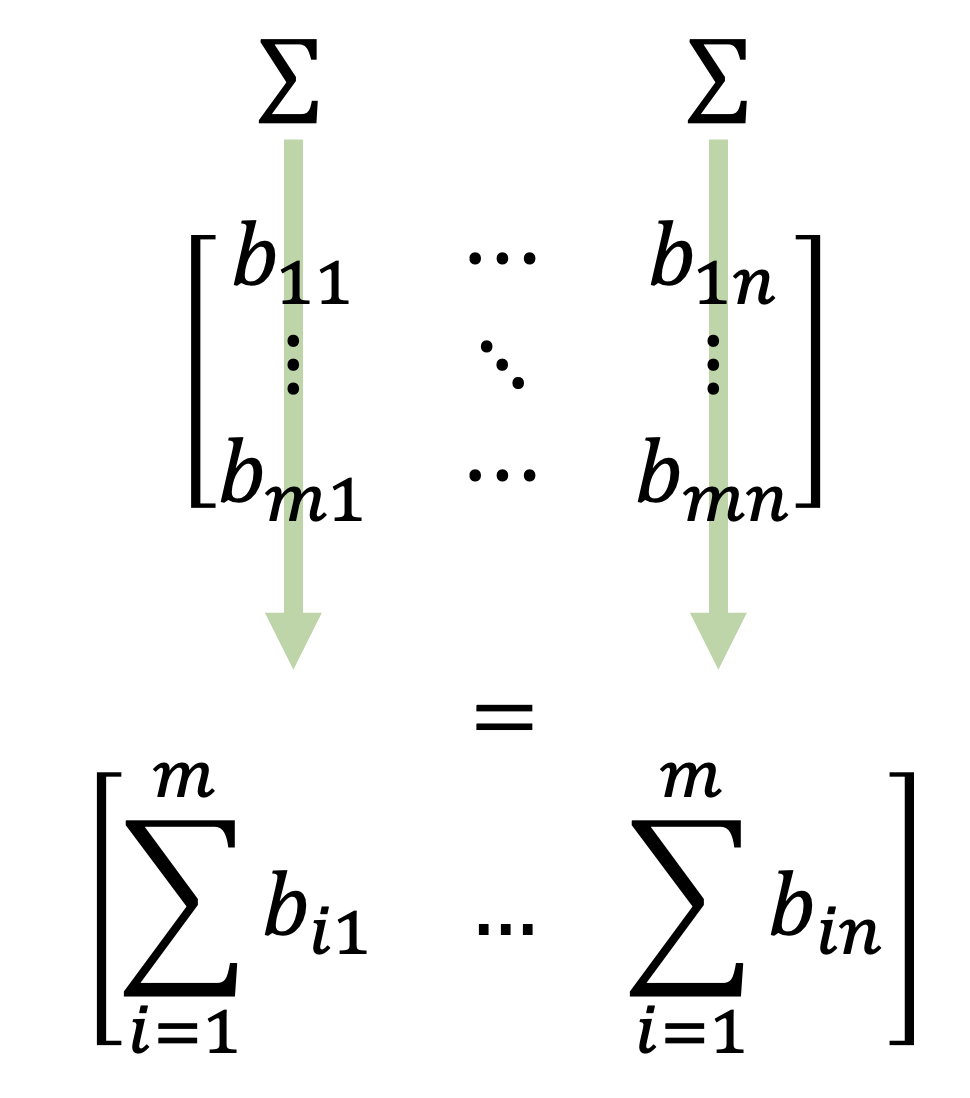

Our algorithm is

- Stop at column (starting from first column)

- Sum the elements from every row of that column

- Store the sum to the corresponding element of a row vector

- Move to next column

- Repeat steps 1 through 4 for all columns of matrix

clear;
B = [1 2 3 4;
    1 2 3 4;
    1 2 3 4];

% preallocate our row vector that will store the sums
b = zeros(1,size(B,2))

b =      0     0     0     0


% outter loop over all columns of B
for n = 1:size(B,2)

    S = 0; % initialize sum to 0 when moving to new column

    % inner loop over all rows of B
    for m = 1:size(B,1)
        % sum successive row elements of nth column of B
        S = S + B(m,n);
    end

    % overwrite element (1,n) of b with nth column sum, S
    b(1,n) = S

end

b =      3     0     0     0


b =      3     6     0     0


b =      3     6     9     0


b =      3     6     9    12


clear;
B = [1 2 3 4;
    1 2 3 4;
    1 2 3 4];

% preallocate our row vector that will store the sums
b = zeros(1,size(B,2));
% outter loop over all columns of B
for p = 1:size(B,2)

    % initialize sum to 0 when moving to new column
    % b(p) = 0;
    % inner loop over all rows of B
    for q = 1:size(B,1)
        % sum successive row elements of nth column of B
        b(p) = b(p) + B(q,p);
    end

    % overwrite element (1,n) of b with nth column sum, S
    

end
disp(b)

     3     6     9    12


disp(sum(B))

     3     6     9    12


disp(sum(B,1))

     3     6     9    12


disp(sum(B,2))

    10
    10
    10
